% TRABAJO MODELADO DE SISTEMAS BIOMÉDICOS
% ANTONIO SÁNCHEZ DOÑA - IVÁN DE LA TORRE SEGATO

clear;
clc;
close all;

% --- 1. DATOS DE LOS PACIENTES (Anexo 1) ---
pacientes = {
    % ID | Edad | Altura | Peso | Sexo | C50  | Gamma
      1,   40,   163,    54,   'F',  6.33,  2.24;
      2,   38,   174,    80,   'F',  6.56,  4.12;
      3,   28,   164,    60,   'M',  4.93,  2.46;
      4,   37,   187,    75,   'M',  8.02,  2.10;
      5,   34,   172,    58,   'F',  4.95,  1.84;
      6,   20,   155,    50,   'F',  1.95,  6.84;
      7,   40,   190,    90,   'M',  8.95,  2.84
};

titulos = {'ID', 'Edad', 'Altura', 'Peso', 'Sexo', 'C50', 'Gamma', ...
           'IMC', 'V1', 'V2', 'V3', 'Cl1', 'Cl2', 'Cl3', ...
           'k10', 'k12', 'k13', 'k21', 'k31'};

Resultados = cell(size(pacientes, 1), length(titulos));
Resultados(:, 1:size(pacientes, 2)) = pacientes;

fprintf('--- Cálculo de Parámetros PK/PD ---\n');

--- Cálculo de Parámetros PK/PD ---



% --- 2. CÁLCULO DE VARIABLES (Schnider) ---
for i = 1:size(pacientes, 1)
    edad = pacientes{i, 2};
    altura = pacientes{i, 3};
    peso = pacientes{i, 4};
    sexo = pacientes{i, 5};
    
    if strcmp(sexo, 'M')
        imc = 1.1 * peso - 128 * (peso / altura)^2;
    else
        imc = 1.07 * peso - 148 * (peso / altura)^2;
    end
    Resultados{i, 8} = imc; 
    
    V1 = 4.27; 
    V2 = 18.9 - 0.391 * (edad - 53);
    V3 = 238;
    Resultados{i, 9} = V1; Resultados{i, 10} = V2; Resultados{i, 11} = V3;

    Cl1 = 1.89 + 0.0456*(peso - 77) - 0.0681*(imc - 59) + 0.0264*(altura - 177);
    Cl2 = 1.29 + 0.024 * (edad - 53);
    Cl3 = 0.836;
    Resultados{i, 12} = Cl1; Resultados{i, 13} = Cl2; Resultados{i, 14} = Cl3;

    k10 = Cl1 / V1; k12 = Cl2 / V1; k13 = Cl3 / V1;
    k21 = Cl2 / V2; k31 = Cl3 / V3;
    
    Resultados{i, 15} = k10; Resultados{i, 16} = k12; Resultados{i, 17} = k13;
    Resultados{i, 18} = k21; Resultados{i, 19} = k31;
end

Resultados = cell2table(Resultados, 'VariableNames', titulos);

% --- 3. CONFIGURACIÓN DE LA SIMULACIÓN ---
modelo_simulink = 'Trabajo';
T_final = 30; 
k1e = 0.456; 
ke0 = 0.456; 

% --- IMPORTANTE: CONFIGURACIÓN DE DOSIS POR DEFECTO PARA LA PARTE 1 ---
% Usaremos una dosis constante de 10 mg/min para comparar a los pacientes.
amp1 = 5; 
amp2 = 0; 
amp3 = 0; 
t_off = 0; 

Resultados_Simulacion = struct();
fprintf('\n--- INICIANDO SIMULACIÓN MULTI-PACIENTE (Dosis fija: %d mg/min) ---\n', amp1);


--- INICIANDO SIMULACIÓN MULTI-PACIENTE (Dosis fija: 5 mg/min) ---



% --- 4. BUCLE PARA SIMULAR A CADA PACIENTE ---
for i = 1:size(Resultados, 1)
    P = Resultados(i, :);
    k10 = P.k10; k12 = P.k12; k13 = P.k13;
    k21 = P.k21; k31 = P.k31;
    C50 = P.C50; Gamma = P.Gamma;

    out = sim(modelo_simulink, 'StopTime', num2str(T_final));

    Resultados_Simulacion(i).ID = P.ID;
    Resultados_Simulacion(i).Time = out.tout; 
    Resultados_Simulacion(i).BIS = out.BIS_Data; 
    Resultados_Simulacion(i).C50 = P.C50;
    Resultados_Simulacion(i).Gamma = P.Gamma;
    
    fprintf('Paciente %d completado.\n', i);
end

Paciente 1 completado.
Paciente 2 completado.
Paciente 3 completado.
Paciente 4 completado.
Paciente 5 completado.
Paciente 6 completado.
Paciente 7 completado.


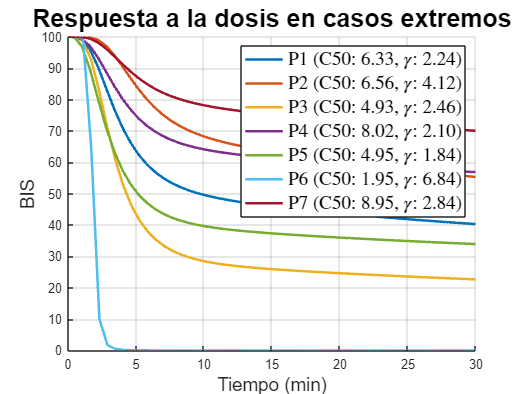


% --- 5. GRÁFICA MULTI-PACIENTE ---
figure; hold on;
for i = 1:size(Resultados_Simulacion, 2)
    label_txt = sprintf('P%d (C50: %.2f, $\\gamma$: %.2f)', ...
        i, Resultados_Simulacion(i).C50, Resultados_Simulacion(i).Gamma);
    plot(Resultados_Simulacion(i).Time, Resultados_Simulacion(i).BIS, 'LineWidth', 2, 'DisplayName', label_txt);
end
grid on; xlabel('Tiempo (min)', 'FontSize', 15); ylabel('BIS', 'FontSize', 15);
title('Respuesta a la dosis en casos extremos', 'FontSize', 20);
legend('show', 'Location', 'NorthEast', 'Interpreter', 'latex', 'FontSize', 15);
hold off;


% --- 6. COMPARATIVA DE DOSIS PARA EL PACIENTE 3 ---
fprintf('\n--- INICIANDO ESCENARIO 3: COMPARATIVA DE DOSIS (P3) ---\n');


--- INICIANDO ESCENARIO 3: COMPARATIVA DE DOSIS (P3) ---


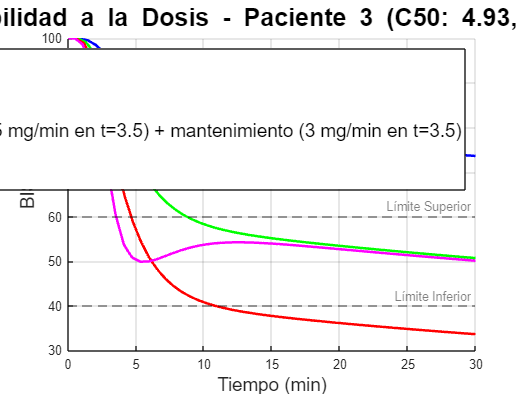


P3 = Resultados(3, :); % Fijamos los parámetros del Paciente 3
k10 = P3.k10; k12 = P3.k12; k13 = P3.k13; k21 = P3.k21; k31 = P3.k31;
C50 = P3.C50; Gamma = P3.Gamma;

% Definimos las 4 dosis a probar
escenarios_dosis = [
    2,  0,  0,  0;    % 2 mg/min
    3,  0,  0,  0;    % 3 mg/min
    4,  0,  0,  0;    % 4 mg/min
    5, -5,  3,  3.5   % Bolo (5) + Mant (3) a los 3.5 min
];
 
nombres_escenarios = {'2 mg/min', '3 mg/min', '4 mg/min', 'Bolo (5 mg/min en t=0,  - 5 mg/min en t=3.5) + mantenimiento (3 mg/min en t=3.5)'};
Resultados_Dosis = struct();

for j = 1:size(escenarios_dosis, 1)
    amp1 = escenarios_dosis(j, 1);
    amp2 = escenarios_dosis(j, 2);
    amp3 = escenarios_dosis(j, 3);
    t_off = escenarios_dosis(j, 4);
    
    out_dosis = sim(modelo_simulink, 'StopTime', num2str(T_final));
    
    Resultados_Dosis(j).Time = out_dosis.tout;
    Resultados_Dosis(j).BIS = out_dosis.BIS_Data;
    Resultados_Dosis(j).Nombre = nombres_escenarios{j};
end

% --- 7. GRÁFICA COMPARATIVA DE DOSIS ---
figure; hold on;
colores = {'b', 'g', 'r', 'm'};
for j = 1:length(Resultados_Dosis)
    plot(Resultados_Dosis(j).Time, Resultados_Dosis(j).BIS, ...
         'Color', colores{j}, 'LineWidth', 2, 'DisplayName', Resultados_Dosis(j).Nombre);
end
yline(60, '--k', 'Límite Superior', 'DisplayName', 'Límite Superior', 'Alpha', 0.5);
yline(40, '--k', 'Límite Inferior', 'DisplayName', 'Límite Inferior', 'Alpha', 0.5);
grid on; xlabel('Tiempo (min)', 'FontSize', 15); ylabel('BIS', 'FontSize', 15);
title(['Sensibilidad a la Dosis - Paciente 3 (C50: ', num2str(double(C50)), ', \gamma: ', num2str(double(Gamma)), ')'], 'FontSize', 20);
legend('show', 'Location', 'NorthEast', 'FontSize', 15);
hold off;


fprintf('\nPROCESO FINALIZADO. SE HAN GENERADO AMBAS GRÁFICAS.\n');


PROCESO FINALIZADO. SE HAN GENERADO AMBAS GRÁFICAS.
